clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\data\state_space


A = table2array(readtable('data/state_space/A.csv'));
B = table2array(readtable('data/state_space/B.csv'));
h = table2array(readtable('data/state_space/h.csv'));
C = table2array(readtable('data/state_space/C.csv'));
D = table2array(readtable('data/state_space/D.csv'));
l = table2array(readtable('data/state_space/l.csv'));
k = table2array(readtable('data/state_space/K.csv'));

sys = ss(A, B, C, D)

sys =
 
  A = 
              x1         x2         x3
   x1  1.388e-06          0          0
   x2   0.007936  -0.002827   0.002237
   x3          0   0.003269   -0.02053
 
  B = 
               u1          u2
   x1  -9.432e-06   -3.94e-06
   x2     -0.1046  -8.395e-05
   x3      0.2018       -3.37
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.


% P = tf(sys);

% Discretization
Ts = 0.1;
sys_d = c2d(sys, Ts, 'zoh')

sys_d =
 
  A = 
              x1         x2         x3
   x1          1          0          0
   x2  0.0007934     0.9997  0.0002235
   x3  1.296e-07  0.0003265     0.9979
 
  B = 
               u1          u2
   x1  -9.432e-07   -3.94e-07
   x2    -0.01046  -4.606e-05
   x3     0.02016     -0.3366
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



A_d = sys_d.A;
B_d = sys_d.B;
C_d = sys_d.C;
D_d = sys_d.D;

Controllability

Co = ctrb(sys);
unco = length(A) - rank(Co)

unco = 0


Co_d = ctrb(sys_d);
unco_d = length(A_d) - rank(Co_d)

unco_d = 0

Observability

Ob = obsv(sys);
unobsv = length(A) - rank(Ob)

unobsv = 0


Ob_d = obsv(sys_d);
unobsv_d = length(A_d) - rank(Ob_d)

unobsv_d = 0

Stability

[V, eig_val] = eigs(A);
eig_val

eig_val =    -0.0209         0         0
         0   -0.0024         0
         0         0    0.0000


eigvec1_op = V(2:end, 2);
eigvec2_op = V(2:end, 3);
slope1_op = eigvec1_op(2) / eigvec1_op(1);
slope2_op = eigvec2_op(2) / eigvec2_op(1);

[V_d, eig_val_d] = eigs(A_d);
eig_val_d

eig_val_d =     1.0000         0         0
         0    0.9998         0
         0         0    0.9979


LQR

T_amb = convtemp(25.0, 'C', 'K');
I_max = 3.0;
R4 = 0.5;
R5 = 25.0;
T_ref = convtemp(37.0, 'C', 'K');
Tc_inf = (T_ref - T_amb) * (R4 + R5) / R5 + T_amb;
T_cell = @(x_Tc) R5 * (x_Tc - T_amb) / (R4 + R5) + T_amb;

q1 = 20 %/ T_amb^2

q1 = 20

Q = [0, 0, 0;
     0, q1, 0;
     0, 0, 0];
r1 = 10 / I_max^2

r1 = 1.1111

r2 = 1

r2 = 1

R = [r1, 0;
     0,  r2];

[K, S, P] = lqr(A, B, Q, R);
A_cl = A - B * K;
[V_cl, eig_val] = eigs(A_cl);
eigvec1_cl = V_cl(2:end, 2);
eigvec2_cl = V_cl(2:end, 3);
slope1_cl = eigvec1_cl(2) / eigvec1_cl(1);
slope2_cl = eigvec2_cl(2) / eigvec2_cl(1);

[K_d, S_d, P_d] = dlqr(A, B, Q, R);
A_cl_d = A_d - B_d * K_d;

RGA

% RGA_matrix = P .* inv(P');
% RGA_freq = evalfr(RGA_matrix, 0)

Phase portraits

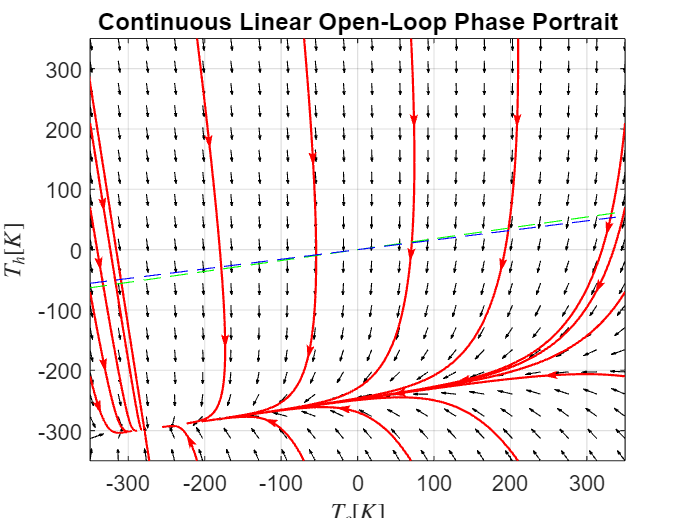

A23 = A(2:3, 2:3);
odefun_open = @(t, x) [A23(1,1)*x(1) + A23(1,2)*x(2) + h(2); %-0.002827147021890*(x - 273.15) + 0.002237389329821*(y - 273.15) + -0.122129663825035
                       A23(2,1)*x(1) + A23(2,2)*x(2) + h(3)]; %0.003269244683906*(x - 273.15) -0.020527653396130*(y - 273.15) + -5.209770202636719
A23_d = A_d(2:3, 2:3);
odefun_open_d = @(t, x) [A23_d(1,1)*x(1) + A23_d(1,2)*x(2) + h(2); %
                         A23_d(2,1)*x(1) + A23_d(2,2)*x(2) + h(3)]; %

A_cl23 = A_cl(2:3, 2:3);
odefun_closed = @(t, x) [A_cl23(1,1)*(x(1) - Tc_inf) + A_cl23(1,2)*x(2) + h(2); %-0.177740807921086*(x - 273.15) + 5.008616595525719e-04*(y - 273.15) + -0.122129663825035
                         A_cl23(2,1)*(x(1) - Tc_inf) + A_cl23(2,2)*x(2) + h(3)]; %-0.314244193898858*(x - 273.15) -0.044649544708827*(y - 273.15) + -5.209770202636719
A_cl23_d = A_cl_d(2:3, 2:3);
odefun_closed_d = @(t, x) [A_cl23_d(1,1)*x(1) + A_cl23_d(1,2)*x(2) + h(2); %
                           A_cl23_d(2,1)*x(1) + A_cl23_d(2,2)*x(2) + h(3)]; %

% Parameters
tspan_op = 400;
tspan_cl = 50;
Tc_limits_op    = [-350, 350];
Th_limits_op    = [-350, 350];
Tc_limits_op_d  = [-350, 350];
Th_limits_op_d  = [-350, 350];
Tc_limits_cl    = [280, 350];
Th_limits_cl    = [-350, 350];
Tc_limits_cl_d  = [-350, 350];
Th_limits_cl_d  = [-350, 350];
% Open-Loop Phase Portrait
figure;
plotpp(odefun_open, 'tspan', tspan_op, 'xlim', Tc_limits_op, 'ylim', Th_limits_op, 'quivercolor', 'k', 'linecolor', 'r')
hold on
plot(Tc_limits_op, slope1_op*Tc_limits_op, '--g');
plot(Tc_limits_op, slope2_op*Tc_limits_op, '--b');
title('Continuous Linear Open-Loop Phase Portrait');
xlabel('$T_c [K]$', Interpreter='latex')
ylabel('$T_h [K]$', Interpreter='latex')
hold off

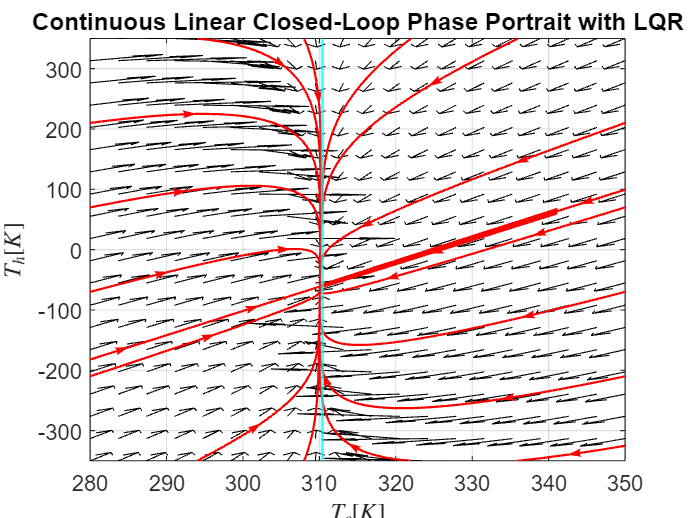


% figure;
% plotpp(odefun_open_d, 'tspan', tspan_op, 'xlim', Tc_limits_op_d, 'ylim', Th_limits_op_d, 'quivercolor', 'k', 'linecolor', 'r')
% title('Discrete Linear Open-Loop Phase Portrait');
% xlabel('$T_c [K]$', Interpreter='latex')
% ylabel('$T_h [K]$', Interpreter='latex')

% Closed-Loop Phase Portrait
figure;
plotpp(odefun_closed, 'tspan', tspan_cl, 'xlim', Tc_limits_cl, 'ylim', Th_limits_cl, 'quivercolor', 'k', 'linecolor', 'r')
hold on
xline(Tc_inf, Color='c', LineWidth=1.5)
plot(Tc_limits_cl - Tc_inf, slope1_cl*(Tc_limits_cl - Tc_inf), '--g');
plot(Tc_limits_cl - Tc_inf, slope2_cl*(Tc_limits_cl - Tc_inf), '--b');
title('Continuous Linear Closed-Loop Phase Portrait with LQR');
xlabel('$T_c [K]$', Interpreter='latex')
ylabel('$T_h [K]$', Interpreter='latex')


% figure;
% plotpp(odefun_closed_d, 'tspan', tspan_cl, 'xlim', Tc_limits_cl_d, 'ylim', Th_limits_cl_d, 'quivercolor', 'k', 'linecolor', 'r')
% title('Discrete Linear Closed-Loop Phase Portrait with LQR');
% xlabel('$T_c [K]$', Interpreter='latex')
% ylabel('$T_h [K]$', Interpreter='latex')